# **三维图、内嵌子图**

**1、三维曲面图(surf)**

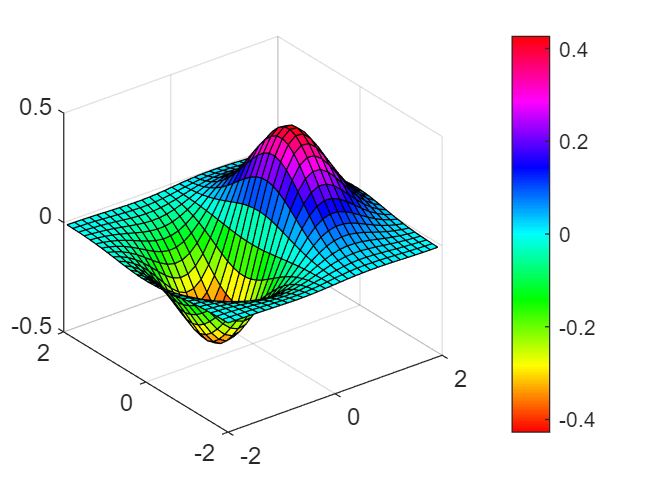

[x,y] = meshgrid(-2:0.14:2); % 创建好x,y空间的点
z = x.*exp(-x.^2-y.^2);
surf(x,y,z)
colormap hsv  % 更改颜色色调
colorbar

**2、子图(subplot)**

在一个图里话很多图表

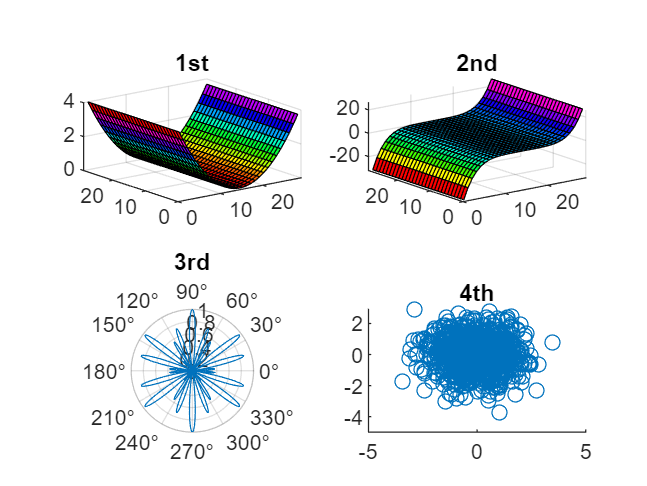

theta = 0:0.01:2*pi;
radi = abs(sin(theta*7).*cos(theta*10));
x = randn(1000,1);
y = randn(1000,1);
[X,Y] = meshgrid(-2:0.14:2); % 创建好x,y空间的点

subplot(2,2,1); % 两行两列，目前的第1个图
surf(X.^2);
title('1st');
subplot(2,2,2);surf(X.^5);title('2nd');
subplot(2,2,3);polarplot(theta, radi);title('3rd');
subplot(2,2,4);scatter(x,y);title('4th');